A = [0,1,0,0;0,0,2,0;0,0,0,3;1/6000,0,0,0];
[eigenvectors, eigenvalues] = eig(A);
[U,sigma,V] = svd(A);
eigenvalues
sigma

B = [3,2;1,4;0.5,0.5];
[V, D] = eig(B' * B);
% lambda = wrev(diag(D));
% V = fliplr(V);
% Sig = zeros(3,2);
V

V =    -0.8481    0.5299
    0.5299    0.8481


for i = 1:1:2
    Sig(i,i) = sqrt(D(i,i));
end
Sig

Sig =     1.9610         0
         0    5.1628
         0         0


[Q,R] = qr(B * V)

Q =    -0.7570   -0.6364   -0.1482
    0.6484   -0.7597   -0.0494
   -0.0811   -0.1335    0.9877


R =     1.9610         0
         0   -5.1628
         0         0


U = Q;
% for i = 1:2
%     U(:,i) = Q(:,i) / (Sig(i,i)/R(i,i));
% end
U

U =    -0.7570   -0.6364   -0.1482
    0.6484   -0.7597   -0.0494
   -0.0811   -0.1335    0.9877


U * Sig * V'

ans =    -0.4823   -3.5732
   -3.1567   -2.6525
   -0.2302   -0.6686



B = [3,2;1,4;0.5,0.5];
[V, D] = eig(B' * B);
lambda = wrev(diag(D));
V = fliplr(V);
Sig = zeros(3,2);
V

V =     0.5299   -0.8481
    0.8481    0.5299


for i = 1:1:2
    Sig(i,i) = sqrt(lambda(i));
end
Sig

Sig =     5.1628         0
         0    1.9610
         0         0


[Q,R] = qr(B * V)

Q =    -0.6364    0.7570   -0.1482
   -0.7597   -0.6484   -0.0494
   -0.1335    0.0811    0.9877


R =    -5.1628         0
         0   -1.9610
         0         0


U = Q;
for i = 1:2
    U(:,i) = Q(:,i) / (Sig(i,i)/R(i,i));
end
U

U =     0.6364   -0.7570   -0.1482
    0.7597    0.6484   -0.0494
    0.1335   -0.0811    0.9877


U * Sig * V'

ans =     3.0000    2.0000
    1.0000    4.0000
    0.5000    0.5000


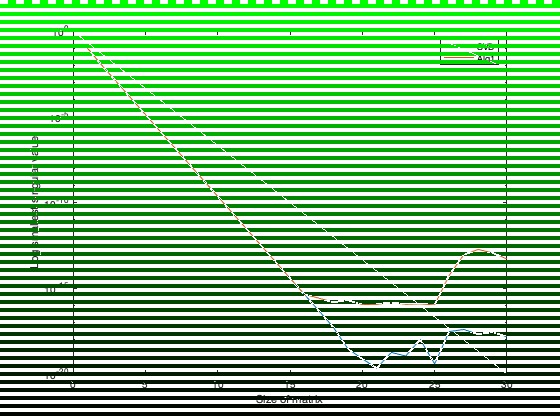

clf;
smallest_svd = [];
smallest_alg1 = [];
for i = 1:1:30
    A = zeros([i,i]);
    for m = 1:i
        for n = m:i
            if m == n
                A(m,n) = 0.1;
            else
                A(m,n) = 1;
            end
        end
    end
    [x, Singular, z] = svd(A);
    smallest_svd = [smallest_svd, min(diag(Singular))];
    
    [V,lambda] = eig(A' * A);
    [Q, R] =qr(A * V);
    smallest_alg1 = [smallest_alg1, min(abs(diag(R)))];
end
semilogy(smallest_svd);
hold on;
semilogy(smallest_alg1);
legend('SVD','Alg1');xlabel('Size of matrix');ylabel('Log smallest singular value');